clear

%% DEFINE THE PLANT INITIAL CONDITIONS

% Initial motor angle [radians]
theta_m_init = deg2rad(45);
% Initial link angle [radians]
theta_l_init = deg2rad(45);
% Initial motor velocity [radians/second]
thetadot_m_init = deg2rad(0);
% Initial link velocity [radians/second]
thetadot_l_init = deg2rad(0);
% Initial motor current [Amps]
Ia_init = 0;

% Initial conditions stacked as a 5x1 vector
init = [theta_m_init; theta_l_init; thetadot_m_init; thetadot_l_init; Ia_init];

%% DEFINE THE SENSOR PARAMETERS

% FOR VISION:
% > The frames per second [fps]
% > Allowed values: 25, 50, 100
vision_fps = 50;

% FOR ABSOLUTE ENCODER
% > Number of counts per revolution
absolute_encoder_counts_per_revolution = 4096;

% FOR POTENTIOMETER
% > Percentage linearity [percent]
potentiometer_linearity_percent = 20;

% FOR TACHOMETER
% > Number of counts per revolution
tachometer_counts_per_revolution = 2048;
% > Frequency of the velocity estimates
% > Allowed values: 10, 25, 50, 100
tachometer_output_frequency = 50;

% FOR GYROSCOPE
% > Variance of the noise that drives the drift process [rad/s^2]
gyro_sigma_drift = deg2rad(5);

Freq=50;

Ts=1/Freq;

Jl =0.001;
m =0.1;
g =9.81;
l =0.1;
Ks =1.75;

% Motor 1

Km =0.5369;
Jm =0.0021;
La =0.18*(10^(-3));
Ra = 2.6;

% % Motor 2
% 
% Km =0.027;
% Jm =7.5*(10^-6);
% La =1.3*(10^(-3));
% Ra = 2;
% 
% %Motor 3
% 
% Km =0.0229;
% Jm =54*(10^-6);
% La =1.3*(10^(-3));
% Ra = 8;

## Task A: Controllabillity and Observability of Full Order Model

Afull=[0 0 1 0 0;0 0 0 1 0;(-Ks/Jm) (Ks/Jm) 0 0 (Km/Jm);(Ks/Jl) (-Ks/Jl-(m*g*l*cosd(30))/(Jl)) 0 0 0;0 0 -Km/La 0 -Ra/La];

Bfull=[0;0;0;0;1/La];

Cfull=[1 0 0 0 0];

D=0;

Gfull=tf(ss(Afull,Bfull,Cfull,D));
% 
% % det(A)
% 
% eig(A);
% 
% % [u,eps,v]=svd(ctrb(A,B),'econ')
% 
% rank(obsv(A,C),1e-5);

## Task B: Reduced Model

A=[0 0 1 0 ;0 0 0 1 ;(-Ks/Jm) (Ks/Jm) -((Km)^2/(Ra*Jm)) 0;(Ks/Jl) (-Ks/Jl-(m*g*l*cosd(30))/(Jl)) 0 0];

B=[0;0;Km/(Ra*Jm);0];

C=[1 0 0 0];

D=0;

Gs=tf(ss(A,B,C,D));
zpk(Gs);
% bode(Gs)
% hold on
% bode(Gfull)
% legend('reduced model','full model');

## Task C1a: Full State Feedback Using Integral Control on Nonlinear model

A_d=[0 1;0 0]; %%disturbance matrix for tracking ramp

B_d=[0;1];

A_aug=[A zeros(4,2);-B_d*C A_d];

B_aug=[B;zeros(2,1)];

C_aug=[C zeros(1,2)];

D_aug=0;

Mp=10;%% percentage overshoot

zeta=(-(log(Mp/100))/(sqrt(pi^2+(log(Mp/100))^2)))+0.31; %% close to overdamped

wn=(-log(0.01*sqrt(1-zeta^2))/zeta);

rts=roots([1 2*zeta*wn wn^2]); %%desired poles

p=[-5.4410+2.6174i;-5.4410-2.6174i;-50;-51;-52;-53];

K_aug=place(A_aug,B_aug,p); %pole placement for augmented model

K_ctr=K_aug(1:4);

K_I=K_aug(end-1:end);

## Task C2: Discrete Full State Feedback Controller using Integral Control

% A_aug_disc=[A zeros(4,2);-B_d*C A_d];
% 
% B_aug_disc=[B;zeros(2,1)];
% 
% C_aug_disc=[C zeros(1,2)];
% 
sys=ss(A,B,C,D);% continuous system
% 
sysd=c2d(sys,Ts,'zoh');%discrete system
% 
A_disc=sysd.A;

B_disc=sysd.B;

C_disc=sysd.C;
% 
ctrb_disc=rank(ctrb(A_disc,B_disc),1e-10);%% ctrb is not lost under sampling

pDisc=exp(([-5.4410+2.6174i;-5.4410-2.6174i;-50;-51]*Ts)); %poles in z-domain
% 
K_disc=place(A_disc,B_disc,pDisc);
% 
K_ctr_disc=K_disc(1:4);
% 
K_I_disc=K_disc(end-1:end);

eig(A_disc-B_disc*K_disc);

## Task D1: Full-order observer on Nonlinear Model

p=[-5.4410+2.6174i;-5.4410-2.6174i;-60;-62]; %%controller poles

p_obs=[-50;-55;-60;-62]; %%observer poles are at least x10 faster than controller poles

Jgain=acker(A',C',[-59;-60;-61;-63])';

## Task D2: Reduced-order Observer

A_11=A_disc(1,1);

A_12=A_disc(1,2:4);

A_21=A_disc(2:4,1);

A_22=A_disc(2:4,2:4);

B_1=B_disc(1,1);

B_2=B_disc(2:4,1);

J_r=place(A_22',A_12',exp([-55,-56,-57].*Ts))'

J_r =     2.2554
   40.3395
 -124.6321



eig(A_22-J_r*A_12);

eig(A_disc);

## Plots

load('error.mat');

load('y.mat')

load('reference.mat')

load('commandu.mat')

load('trueu.mat')

load('plantstates.mat')

load('LuenbergerStates.mat')

load('truth.mat')

load('full.mat')

load('rob.mat')

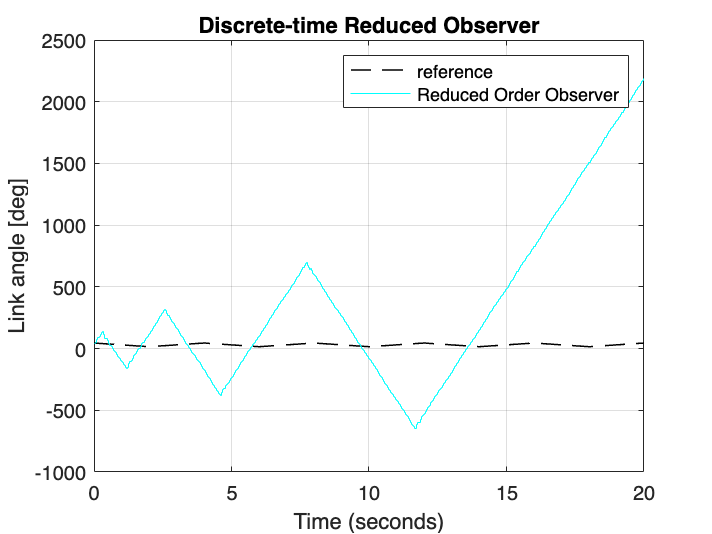

plot(reference,'k--','LineWidth',0.75)

hold on
grid on
plot(y,'c')
ylabel('Link angle [deg]')
title('Discrete-time Reduced Observer')
legend('reference','Reduced Order Observer')
hold off

plot(full,'m-','LineWidth',0.75)

hold on

plot(rob,'b--','LineWidth',0.1)

grid on

ylabel('Link angle [deg]')

legend('reference','Luenberger Observer','Reduced Order Observer')

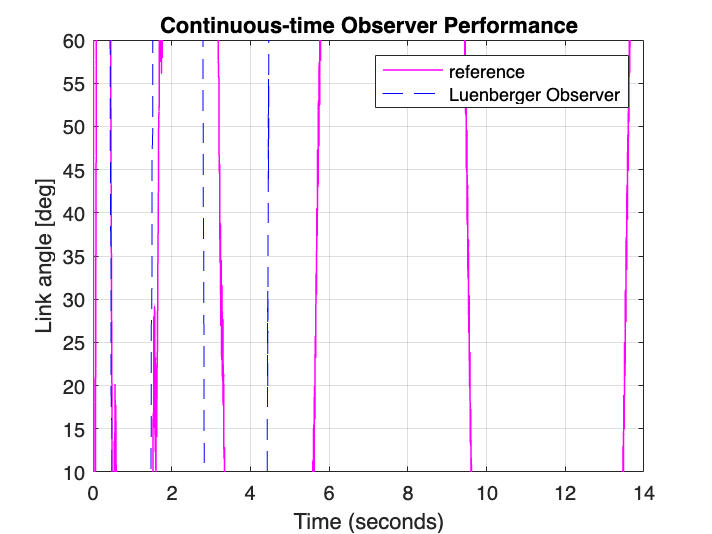


ylim([10 60])

title('Continuous-time Observer Performance')

hold off

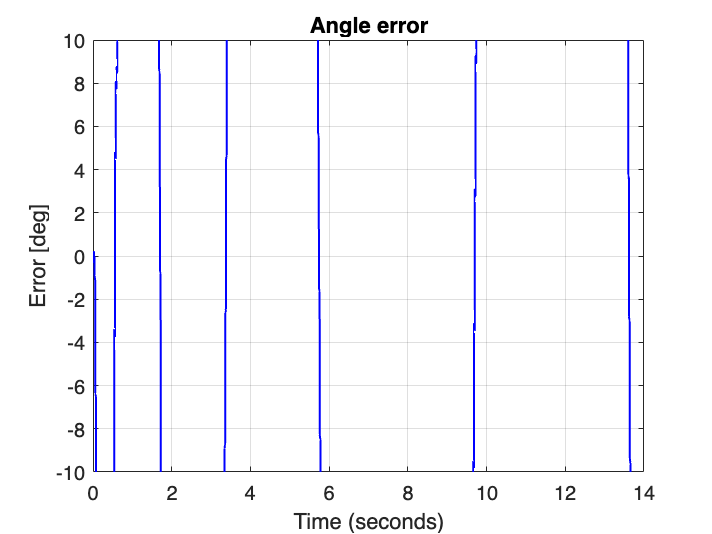


plot(Error,'b-','LineWidth',1)
grid on

ylim([-10 10])

ylabel('Error [deg]')

title('Angle error')

hold off

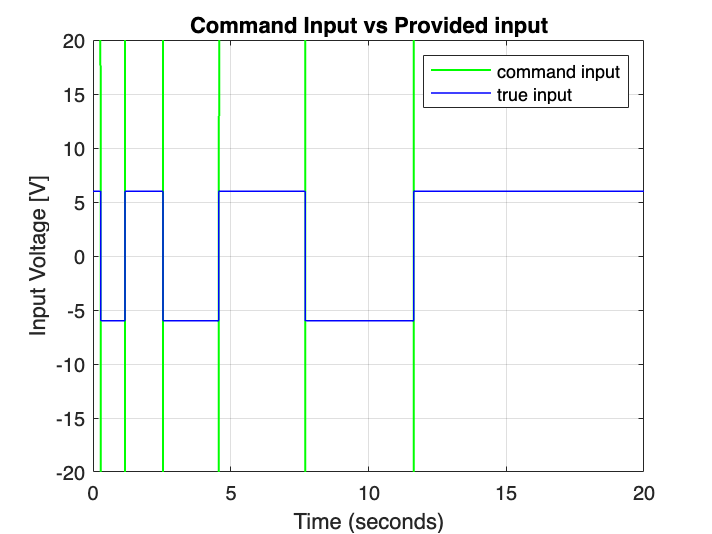


plot(commandu,'g-','LineWidth',1,'MarkerSize',2)

grid on

hold on

plot(trueu,'b-','LineWidth',0.75,'MarkerSize',2)

ylim([-20 20])

ylabel('Input Voltage [V]')

title('Command Input vs Provided input')

legend('command input','true input')

hold off

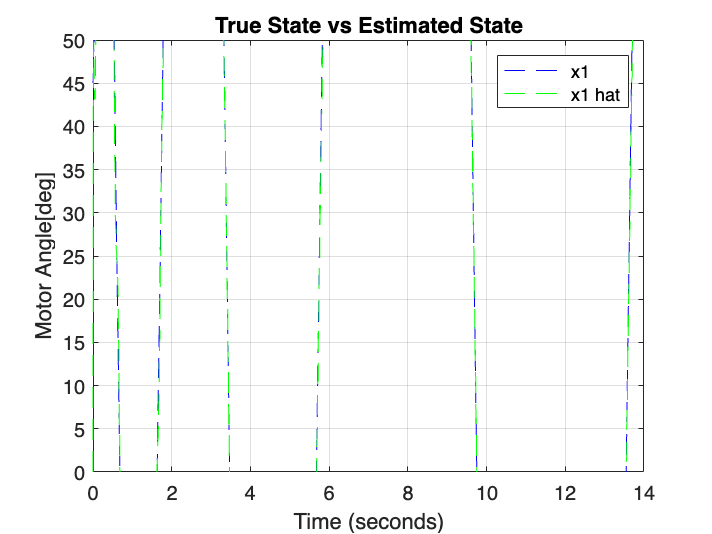


plot(plantstates,'b--')

grid on

ylim([0 50])

ylabel('Motor Angle[deg]')

hold on

plot(LuenbergerStates,'g--')

title('True State vs Estimated State')

legend('x1','x1 hat')

hold off

## At-Sample Design

% G_ss=ss(A,B,C,D);
% 
% G_ss_disc =c2d(G_ss,Ts,'zoh'); %%discrete plant
% 
% A_disc=G_ss_disc.A;
% 
% B_disc=G_ss_disc.B;
% 
% C_disc=G_ss_disc.C;
% 
% D_disc=G_ss_disc.D;
% 
% p_disc=exp(([real((rts(1,:)));
%       real((rts(2,:)))-1;
%     5*real(rts(1,:))-3;
%     5*real(rts(1,:)-5);
%     5*real(rts(1,:)-7);
%     5*real(rts(1,:)-9)])*Ts)
% 
% % p_disc=exp(Ts*p)
% 
% % K_disc=acker(A_disc,B_disc,p_disc) %%discrete controller
% 
% A_aug_disc=[A_disc zeros(4,2);-B_d*C_disc A_d];
% 
% B_aug_disc=[B_disc;zeros(2,1)];
% 
% C_aug_disc=[C_disc zeros(1,2)];
% 
% D_aug_disc=0;
% 
% K_disc2=place(A_aug_disc,B_aug_disc,p_disc);
% 
% K_ctr_disc=K_disc2(1:4)
% 
% K_I_disc=K_disc2(end-1:end)
% 
% eig(A_aug_disc-K_disc2.*B_aug_disc);

## Task E

w=pi/2;

Ap_sine=[0 w;-w 0]; %%disturbance matrix for tracking ramp

Bp_sine=[0;1];

A_aug_sine=[A zeros(4,2);-Bp_sine*C Ap_sine];

B_aug_sine=[B;zeros(2,1)];

C_aug_sine=[C zeros(1,2)];

D_aug_sine=0;

K_aug_sine=place(A_aug_sine,B_aug_sine,[-5.4410+2.6174i;-5.4410-2.6174i;-60;-65;-70;-75]); %pole placement for augmented model

K_ctr_sine=K_aug_sine(1:4);

K_I_sine=K_aug_sine(end-1:end);

s=tf('s');

Mp=10; %%how much overshoot as a percentage

zeta_min=-(log(Mp/100))/(sqrt(pi^2+(log(Mp/100))^2)); %%minimum value zeta can take

zeta=0.8; %actual zeta value we will use

wn_min=(1/(2*zeta))*log(100/(2*(sqrt(1-zeta^2))))

wn_min = 2.7643


wn=wn_min;

Mf_min=atand(2*zeta/(sqrt(sqrt(1+4*(zeta)^4)-2*zeta^2))) %%minimum phase margin we must try achieve

Mf_min = 69.8600


Mf=75*(pi/180); %actual phase margin im designing for

wc_min=wn*sqrt(sqrt(1+(4*(zeta^4)))-2*(zeta)^2) %%must be greater than this value

wc_min = 1.6220


wc=9; %%actual value we will use

tz2=10/wc;

tp=1/(10*wc);

%%%finding tz1 by rearranging eq 19 from Workshop 1
q=wc*1i; %(s)

phaseGC=angle(q*tz2+1)-angle(q)-angle(q*tp+1)-angle(q+1.439e04)-angle(q+43.41)-angle(q+0.8516)-angle((q^2)+8.726*q+1966);

tz1=(tan(Mf-pi-phaseGC))/wc

tz1 = 0.0100


%%%finding K by rearranging eq 20 from Workshop 1
syms t;

numtf=2.2016e9; %numerator of tf with symbolic variable t replacing s

dentf=(t+1.439e04)*(t+43.41)*(t+0.8516)*(t^2+8.726*t+1966); %denominator of tf with symbolic variable t replacing s

G2=numtf/dentf; %transfer function with symbolic variable t replacing s

G3=subs(G2,t,wc*1i);%replace t with wc*j

magG=double((abs(G3))); %magnitude of tf evaluated at wc

K_gain=double((wc*abs(tp*wc*1i+1))/(abs(tz1*wc*1i+1)*abs(tz2*wc*1i+1)*magG)) %%lower bound

K_gain = 4.4300


C_pid=K_gain*(((tz1*s)+1)*((tz2*s)+1))/((s)*((tp*s)+1))

C_pid =
 
  0.04929 s^2 + 4.967 s + 4.43
  ----------------------------
        0.01111 s^2 + s
 
Continuous-time transfer function.



## Discretising controller with sampling time Ts

Cz_zoh=c2d(C_pid,Ts,'zoh');

Cz_euler=c2d_euler(C_pid,Ts,'forward');